clear
clc
close all

z = tf('z',1);

agora vem a função de transferência:


$$\left(1-1\ldotp 5q^{-1} +0\ldotp 7q^{-2} \right)y\left(k\right)=\left(1+0\ldotp 9q^{-1} \right)u\left(k-1\right)$$



$$\left(1-1\ldotp 5q^{-1} +0\ldotp 7q^{-2} \right)y\left(k\right)=\left(q^{-1} +0\ldotp 9q^{-2} \right)u\left(k\right)$$



$$\left(q^2 -1\ldotp 5q^1 +0\ldotp 7\right)y\left(k\right)=\left(q+0\ldotp 9\right)u\left(k\right)$$



$$\textrm{Gz}=\frac{z+0\ldotp 9}{z^2 +1\ldotp 5z+0\ldotp 7}$$


Gz = (z+0.9)/(z^2-1.5*z+0.7)

Gz =
 
       z + 0.9
  -----------------
  z^2 - 1.5 z + 0.7
 
Sample time: 1 seconds
Discrete-time transfer function.
Model Properties


resposta ao impulso

g = impulse(Gz,50);
g(1:20)

ans =          0
    1.0000
    2.4000
    2.9000
    2.6700
    1.9750
    1.0935
    0.2578
   -0.3788
   -0.7487



s = step(Gz,50);
s(1:10)

ans =          0
    1.0000
    3.4000
    6.3000
    8.9700
   10.9450
   12.0385
   12.2962
   11.9174
   11.1688


s10 = s(1:10);

Para gerar a matriz G:    

% MATRIZ G (Ny = 10, Nc = 10)
Ny = 10;
Nc = 10;
G = zeros(Ny,Nc);

for j = 1:Ny                  % linha
    for i = 1:Nc              % coluna
        if (j - i + 1) > 0
            G(j,i) = s10(j - i + 1);
        else
            G(j,i) = 0;
        end
    end
end

% Mostrar a matriz (formato de matriz mesmo)
disp('Matriz G = ');

Matriz G = 


disp(G);

         0         0         0         0         0         0         0         0         0         0
    1.0000         0         0         0         0         0         0         0         0         0
    3.4000    1.0000         0         0         0         0         0         0         0         0
    6.3000    3.4000    1.0000         0         0         0         0         0         0         0
    8.9700    6.3000    3.4000    1.0000         0         0         0         0         0         0
   10.9450    8.9700    6.3000    3.4000    1.0000         0         0         0         0         0
   12.0385   10.9450    8.9700    6.3000    3.4000    1.0000         0         0         0         0
   12.2962   12.0385   10.9450    8.9700    6.3000    3.4000    1.0000         0         0         0
   11.9174   12.2962   12.0385   10.9450    8.9700    6.3000    3.4000    1.0000         0         0
   11.1688   11.9174   12.2962   12.0385   10.9450    8.9700    6.3000    3.4000    1.0000 

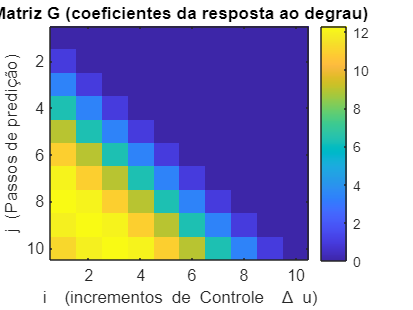


%--------------------------------------------------------
% GRÁFICO DA MATRIZ G
figure;
imagesc(G);
colorbar;
title('Matriz G (coeficientes da resposta ao degrau)');
xlabel('i  (incrementos de Controle  \Delta u)');
ylabel('j  (Passos de predição)');

para gerar um grafico é só fazer o seguinte ( esse seria um grafico do impulso, por 50 segundos)

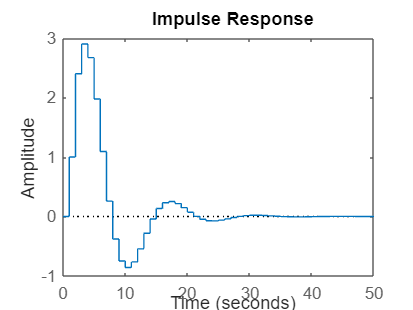

impulse(Gz,50)